% readTimeDomainResults  Reads in results from a single simulationBladeBody
%
close all
clear all
clc

folderF1 = 'E:\DecayResults\Blade\Forces\Forces_1';
folderF2 = 'E:\DecayResults\Blade\Forces\Forces_2';
folderF3 = 'E:\DecayResults\Blade\Forces\Forces_3';

folderM1 = 'E:\DecayResults\Blade\Moments\Moments_1';
folderM2 = 'E:\DecayResults\Blade\Moments\Moments_2';
folderM3 = 'E:\DecayResults\Blade\Moments\Moments_3';

prefix = 'sima';
BladeBody = 2; % typically 1
numForChan = 116; % this is the number of channels in the force results ...123 original
% storage. You can find this in the key_sima_elmfor.txt file.


## F1 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderF1 '\results.txt']);
% Read the binary file
AAF1 = read_simoresults([folderF1 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Blade\Forces\Forces_1\results.tda


sizeAAF1 = size(AAF1);
if (sizeAAF1(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[BladeMotionsF1, BladeWaveF1] = getchannelNumbers(chanNames,BladeBody);
if (BladeMotionsF1(1)<1 || BladeWaveF1<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transF1=350; %s
AAF1(1:(transF1/dt),:)=[];
time_SIMO_F1 = AAF1(:,2);
% summarize data in matrix
BladeMotionsF1 = AAF1(:,BladeMotionsF1);
BladewaveF1 = AAF1(:,BladeWaveF1);


BladeXg_F1=BladeMotionsF1(:,1);
BladeYg_F1=BladeMotionsF1(:,2);
BladeZF1=BladeMotionsF1(:,3);

phi=deg2rad(-30);
BladeXgF1=BladeXg_F1*cos(phi)-BladeYg_F1*sin(phi);
BladeYgF1=BladeXg_F1*sin(phi)+BladeYg_F1*cos(phi);


[pks,locs] = findpeaks(BladeXgF1,time_SIMO_F1);
periodXF1 = max(diff(locs));


[fpsd_F1, psd_F1] = Power_Spectral_Density(time_SIMO_F1,BladeXgF1);


## F2 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderF2 '\results.txt']);
% Read the binary file
AAF2 = read_simoresults([folderF2 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Blade\Forces\Forces_2\results.tda


sizeAAF2 = size(AAF2);
if (sizeAAF2(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[BladeMotionsF2, BladeWaveF2] = getchannelNumbers(chanNames,BladeBody);
if (BladeMotionsF2(1)<1 || BladeWaveF2<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transF2=350; %s
AAF2(1:(transF2/dt),:)=[];
time_SIMO_F2 = AAF2(:,2);
% summarize data in matrix
BladeMotionsF2 = AAF2(:,BladeMotionsF2);
BladewaveF2 = AAF2(:,BladeWaveF2);

BladeXg_F2=BladeMotionsF2(:,1);
BladeYg_F2=BladeMotionsF2(:,2);
BladeZF2=BladeMotionsF2(:,3);

phi=deg2rad(-30);
BladeXgF2=BladeXg_F2*cos(phi)-BladeYg_F2*sin(phi);
BladeYgF2=BladeXg_F2*sin(phi)+BladeYg_F2*cos(phi);
[pks,locs] = findpeaks(BladeYgF2,time_SIMO_F2);
periodYF2 = max(diff(locs))

periodYF2 = 17



[fpsd_F2, psd_F2] = Power_Spectral_Density(time_SIMO_F2,BladeYgF2);

##  F3 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderF3 '\results.txt']);
% Read the binary file
AAF3 = read_simoresults([folderF3 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Blade\Forces\Forces_3\results.tda


sizeAAF3 = size(AAF3);
if (sizeAAF3(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[BladeMotionsF3, BladeWaveF3] = getchannelNumbers(chanNames,BladeBody);
if (BladeMotionsF3(1)<1 || BladeWaveF3<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transF3=200; %s
AAF3(1:(transF3/dt),:)=[];
time_SIMO_F3 = AAF3(:,2);
% summarize data in matrix
BladeMotionsF3 = AAF3(:,BladeMotionsF3);
BladewaveF3 = AAF3(:,BladeWaveF3);

BladeXgF3=BladeMotionsF3(:,1);
BladeYgF3=BladeMotionsF3(:,2);
BladeZF3=BladeMotionsF3(:,3);
[pks,locs] = findpeaks(BladeZF3(1:1500),time_SIMO_F3(1:1500));
periodZF3 = max(diff(locs))

periodZF3 = 0.8000



[fpsd_F3, psd_F3] = Power_Spectral_Density(time_SIMO_F3(1:1500),BladeZF3(1:1500));

## M1 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderM1 '\results.txt']);
% Read the binary file
AAM1 = read_simoresults([folderM1 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Blade\Moments\Moments_1\results.tda


sizeAAM1 = size(AAM1);
if (sizeAAM1(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[BladeMotionsM1, BladeWaveM1] = getchannelNumbers(chanNames,BladeBody);
if (BladeMotionsM1(1)<1 || BladeWaveM1<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transM1=250; %s
AAM1(1:(transM1/dt),:)=[];
time_SIMO_M1 = AAM1(:,2);
% summarize data in matrix
BladeMotionsM1 = AAM1(:,BladeMotionsM1);
BladewaveM1 = AAM1(:,BladeWaveM1);

BladeXgM1=BladeMotionsM1(:,4);
BladeYgM1=BladeMotionsM1(:,5);
BladeZM1=BladeMotionsM1(:,6);
[pks,locs] = findpeaks(BladeXgM1(1:2500),time_SIMO_M1(1:2500));
periodXM1 = max(diff(locs))

periodXM1 = 17



[fpsd_M1, psd_M1] = Power_Spectral_Density(time_SIMO_M1(1:2500),BladeXgM1(1:2500));

## M2 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderM2 '\results.txt']);
% Read the binary file
AAM2 = read_simoresults([folderM2 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Blade\Moments\Moments_2\results.tda


sizeAAM2 = size(AAM2);
if (sizeAAM2(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[BladeMotionsM2, BladeWaveM2] = getchannelNumbers(chanNames,BladeBody);
if (BladeMotionsM2(1)<1 || BladeWaveM2<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transM2=250; %s
AAM2(1:(transM2/dt),:)=[];
time_SIMO_M2 = AAM2(:,2);
% summarize data in matrix
BladeMotionsM2 = AAM2(:,BladeMotionsM2);
BladewaveM2 = AAM2(:,BladeWaveM2);

BladeXgM2=BladeMotionsM2(:,4);
BladeYgM2=BladeMotionsM2(:,5);
BladeZM2=BladeMotionsM2(:,6);
[pks,locs] = findpeaks(BladeYgM2(1:2000),time_SIMO_M2(1:2000));
periodYM2 = max(diff(locs))

periodYM2 = 7.6000


[fpsd_M2, psd_M2] = Power_Spectral_Density(time_SIMO_M2(1:2000),BladeYgM2(1:2000));

## M3 Output

%==========================================================================
%%READ SIMULATION OUTPUT
% Read the SIMO results text file to get the channel names and number
% of steps

[nchan, nts, dt, chanNames] = readSIMO_resultstext([folderM3 '\results.txt']);
% Read the binary file
AAM3 = read_simoresults([folderM3 '\results.tda'],nts);

 ... Binary file read: E:\DecayResults\Blade\Moments\Moments_3\results.tda


sizeAAM3 = size(AAM3);
if (sizeAAM3(1)<nts || nts<1); disp('Unable to read SIMO results'); return; end;
% Determine which channels to read for the platform motions, wave
% elevation
[BladeMotionsM3, BladeWaveM3] = getchannelNumbers(chanNames,BladeBody);
if (BladeMotionsM3(1)<1 || BladeWaveM3<1); disp('Unable to read SIMO results'); return; end;


%discard transient
transM3=250; %s
AAM3(1:(transM3/dt),:)=[];
time_SIMO_M3 = AAM3(:,2);
% summarize data in matrix
BladeMotionsM3 = AAM3(:,BladeMotionsM3);
BladewaveM3 = AAM3(:,BladeWaveM3);

BladeXgM3=BladeMotionsM3(:,4);
BladeYgM3=BladeMotionsM3(:,5);
BladeZgM3=BladeMotionsM3(:,6);

BladeZlM3=zeros(1,length(BladeZgM3));
for k=1:length(BladeZgM3)
    if BladeZgM3(k)>0
        BladeZlM3(k)=BladeZgM3(k)-270;
    end
    if BladeZgM3(k)<0
        BladeZlM3(k)=BladeZgM3(k)+90;
    end
end
[pks,locs] = findpeaks(BladeZlM3,time_SIMO_M3);
periodZM3 = max(diff(locs))

periodZM3 = 80.3000


[fpsd_M3, psd_M3] = Power_Spectral_Density(time_SIMO_M3,BladeZlM3);

## Plots

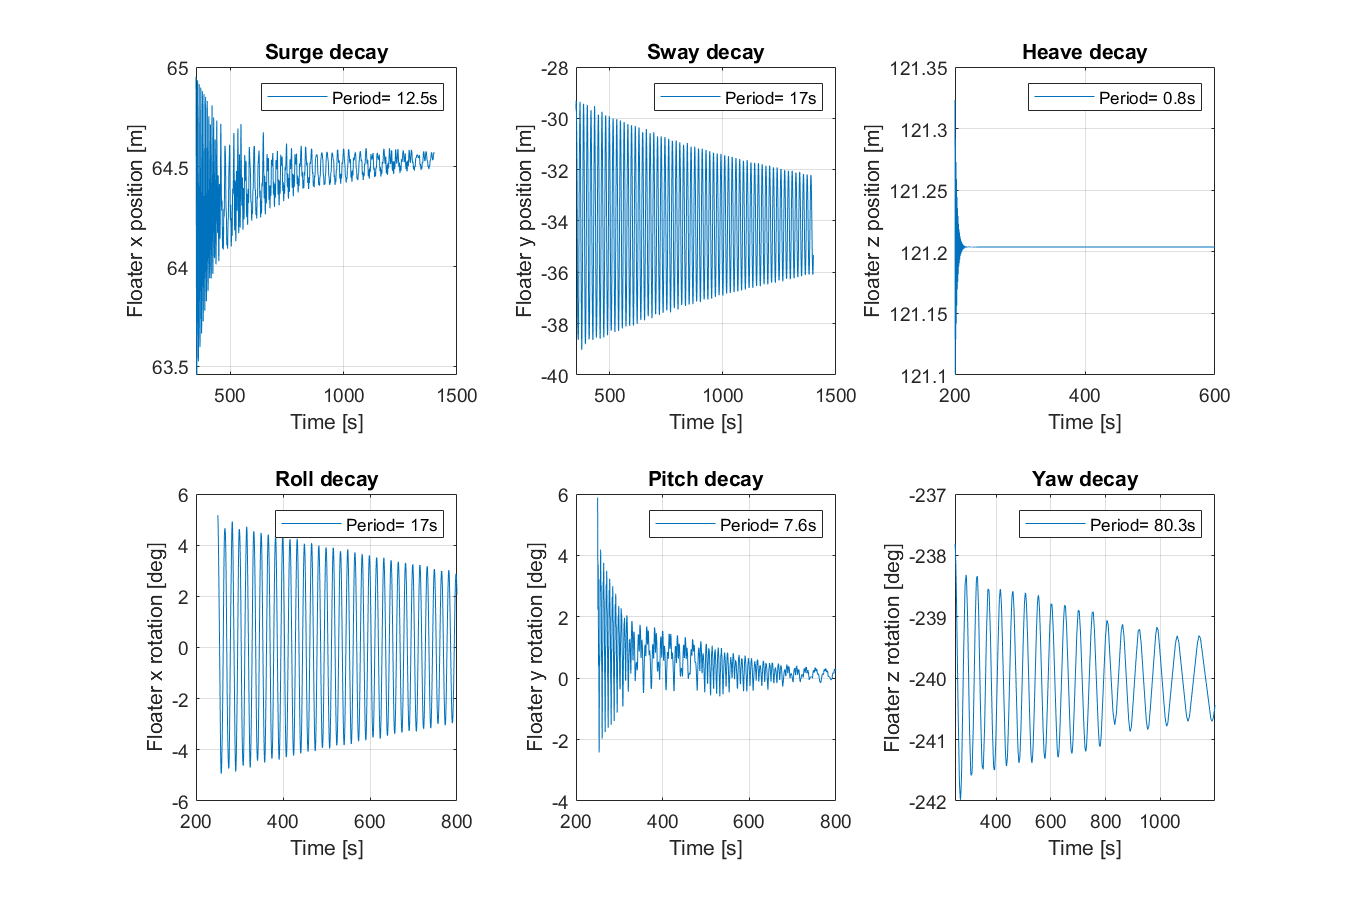

%time series
f=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
subplot(2,3,1)
legper=num2str(periodXF1);
leglab=['Period= ' legper 's'];

plot(time_SIMO_F1,BladeXgF1)
grid on
title('Surge decay')
xlabel('Time [s]')
ylabel('Floater x position [m]')
legend(leglab)

subplot(2,3,2)
legper=num2str(periodYF2 );
leglab=['Period= ' legper 's'];
plot(time_SIMO_F1,BladeYgF2)
grid on
title('Sway decay')
xlabel('Time [s]')
ylabel('Floater y position [m]')
legend(leglab)

subplot(2,3,3)
legper=num2str(periodZF3 );
leglab=['Period= ' legper 's'];
plot(time_SIMO_F3,BladeZF3)
grid on
title('Heave decay')
xlabel('Time [s]')
ylabel('Floater z position [m]')
legend(leglab)

subplot(2,3,4)
legper=num2str(periodXM1 );
leglab=['Period= ' legper 's'];

plot(time_SIMO_M1,BladeXgM1)
grid on
title('Roll decay')
xlabel('Time [s]')
ylabel('Floater x rotation [deg]')
legend(leglab)

subplot(2,3,5)
legper=num2str(periodYM2 );
leglab=['Period= ' legper 's'];

plot(time_SIMO_M1,BladeYgM2)
grid on
title('Pitch decay')
xlabel('Time [s]')
ylabel('Floater y rotation [deg]')
legend(leglab)

subplot(2,3,6)
legper=num2str(periodZM3 );
leglab=['Period= ' legper 's'];

plot(time_SIMO_M3,BladeZlM3)
grid on
title('Yaw decay')
xlabel('Time [s]')
ylabel('Floater z rotation [deg]')
legend(leglab)


exportgraphics(f,'BladeDecay_Time.pdf')

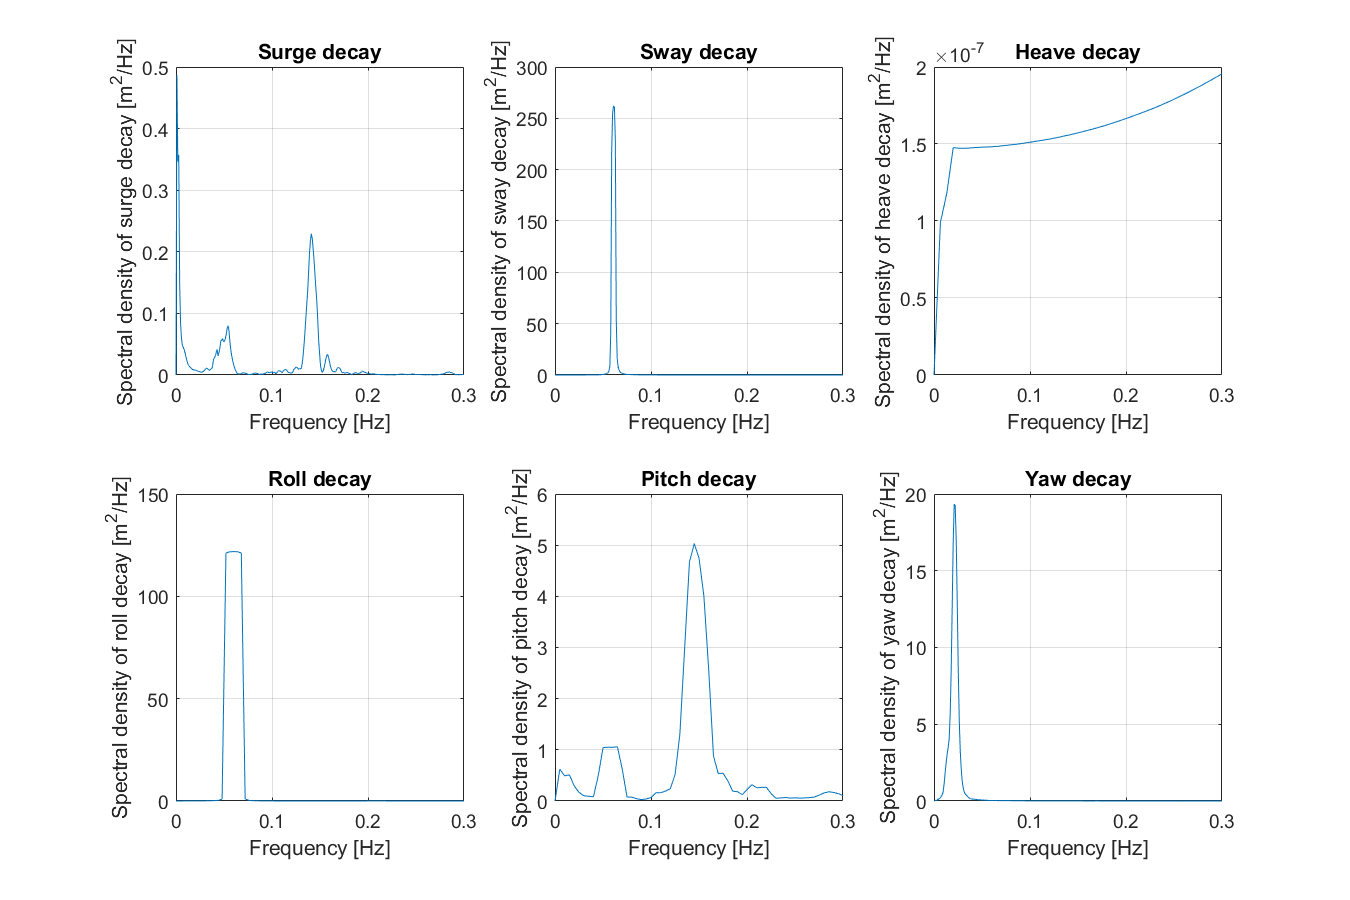


%psds
f2=figure('Renderer', 'painters', 'Position', [10 10 900 600]);
subplot(2,3,1)
plot(fpsd_F1, smooth(psd_F1))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of surge decay [m^2/Hz]')
title('Surge decay')
xlim([0 0.3])

subplot(2,3,2)
plot(fpsd_F2, smooth(psd_F2))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of sway decay [m^2/Hz]')
title('Sway decay')
xlim([0 0.3])

subplot(2,3,3)
plot(fpsd_F3, smooth(psd_F3))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of heave decay [m^2/Hz]')
title('Heave decay')
xlim([0 0.3])

subplot(2,3,4)
plot(fpsd_M1, smooth(psd_M1))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of roll decay [m^2/Hz]')
title('Roll decay')
xlim([0 0.3])


subplot(2,3,5)
plot(fpsd_M2, smooth(psd_M2))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of pitch decay [m^2/Hz]')
title('Pitch decay')
xlim([0 0.3])

subplot(2,3,6)
plot(fpsd_M3, smooth(psd_M3))
grid on
xlabel('Frequency [Hz]')
ylabel('Spectral density of yaw decay [m^2/Hz]')
title('Yaw decay')
xlim([0 0.3])

figure('Renderer', 'painters', 'Position', [10 10 900 600]);
exportgraphics(f2,'BladeDecay_RAO.pdf')